# 需求分析：LSTM （长短期记忆神经网络）时间序列预测

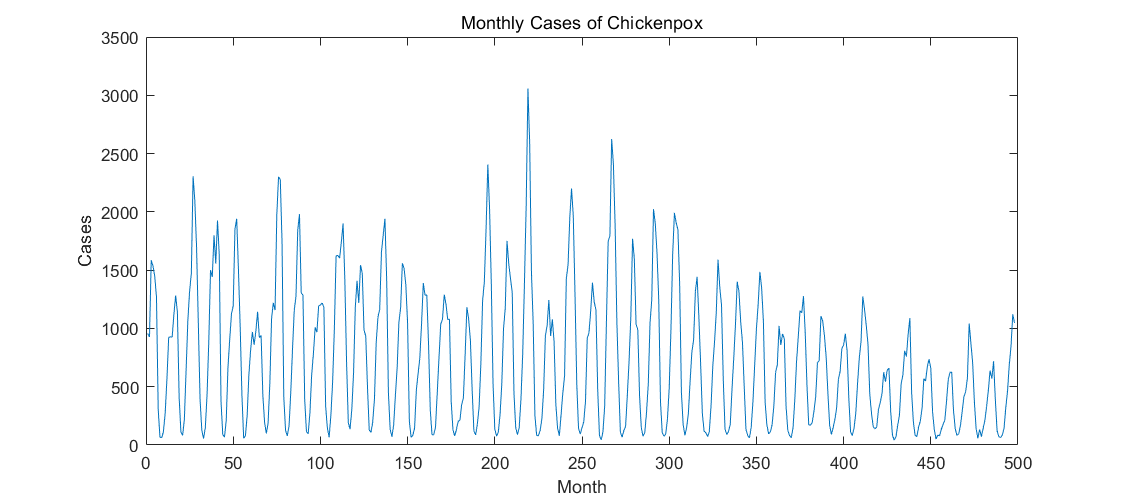

clear;clc;close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 加载数据
data = chickenpox_dataset;
data = cell2mat(data);
% 绘图
figure('Position', [10, 10, 900, 400]);
plot(data);
xlabel("Month");
ylabel("Cases");
title("Monthly Cases of Chickenpox");
% 训练集和测试集
numTimeStepsTrain = floor(0.9*numel(data));
dataTrain = data(1 : numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1 : end);
% 数据标准化，零均值和单位方差
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
% 训练数据
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 创建 LSTM 网络
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 200;
layers = [sequenceInputLayer(numFeatures)
          lstmLayer(numHiddenUnits)
          fullyConnectedLayer(numResponses)
          regressionLayer];
% 设置网络参数
options = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 125, ...
    'LearnRateDropFactor', 0.2, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
% 训练
net = trainNetwork(XTrain,YTrain,layers,options);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 预测
% 数据标准化
dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1 : end-1);
% 初始化网络，先对训练数据 XTrain 进行预测
net = predictAndUpdateState(net, XTrain);
% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[net, YPred] = predictAndUpdateState(net, YTrain(end));
% 循环其余预测，使用前一次的预测结果作为输入
numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net, YPred(:, i)] = predictAndUpdateState(net, YPred(:, i-1), 'ExecutionEnvironment', 'cpu');
end
% 去标准化
YPred = sig*YPred + mu;
% 计算均方误差
YTest = dataTest(2:end);
err = YPred - YTest;
rmse = sqrt(mean(err.^2));

rmse = single
170.0514

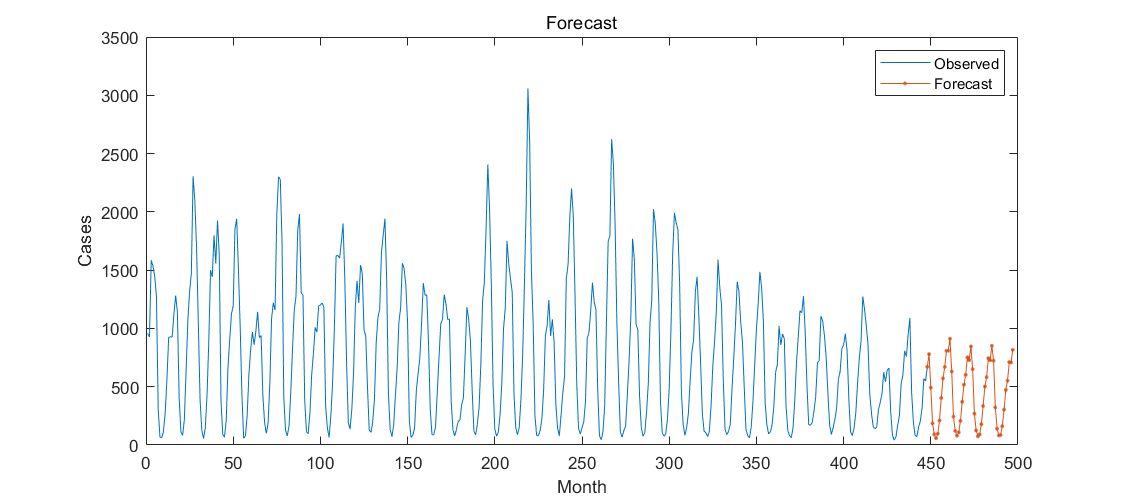

% 画图
figure('Position', [10, 10, 900, 400]);
plot(dataTrain(1 : end-1))
hold on
idx = numTimeStepsTrain : (numTimeStepsTrain + numTimeStepsTest);
plot(idx, [data(numTimeStepsTrain) YPred], '.-')
hold off 
xlabel("Month");
ylabel("Cases");
title("Forecast");
legend("Observed", "Forecast");

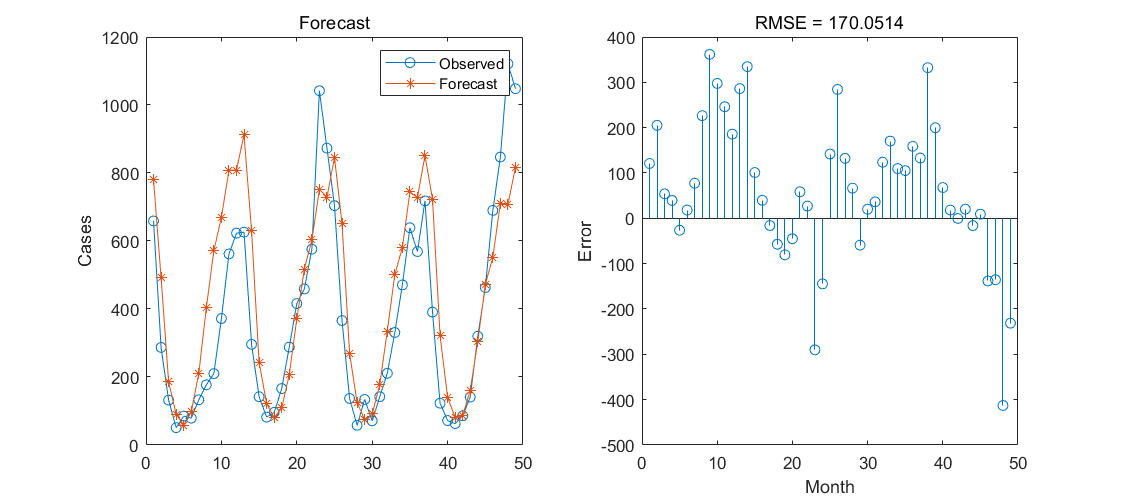

% 绘图比较
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1)
plot(YTest, '-o');
hold on
plot(YPred, '-*');
hold off
legend("Observed", "Forecast");
ylabel("Cases");
title("Forecast");
subplot(1, 2, 2)
stem(err);
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

% 重置网络状态，防止先前的预测结果影响新数据预测
net = resetState(net);
% 预测训练数据来初始化网络状态
net = predictAndUpdateState(net, XTrain);
numTimeStepsTest = numel(XTest);
for i = 1 : numTimeStepsTest
    [net, YPred(:, i)] = predictAndUpdateState(net, XTest(:, i), 'ExecutionEnvironment','cpu');
end
% 去标准化
YPred = sig*YPred + mu;
% 计算均方误差
err = YPred - YTest;
rmse = sqrt(mean(err.^2))

rmse = 126.1408

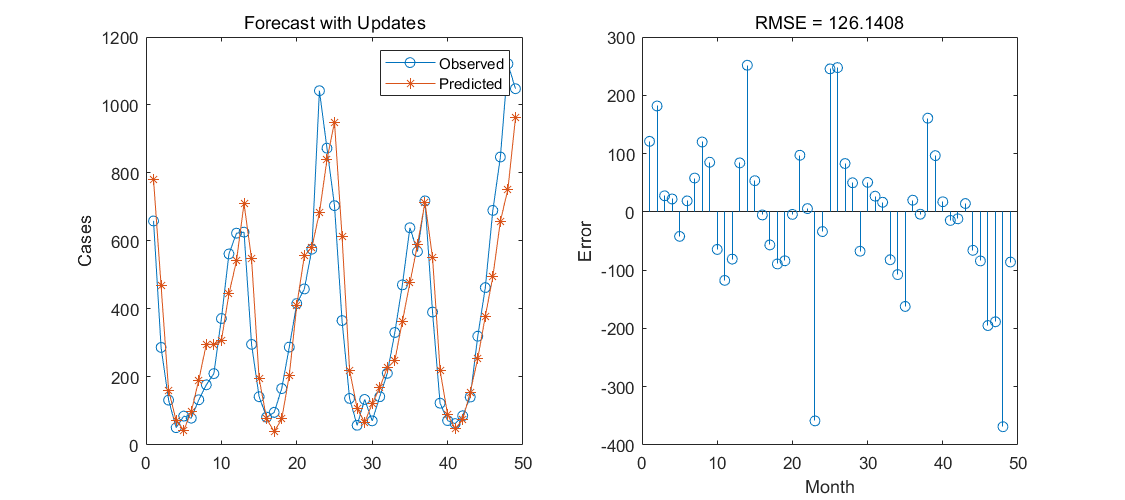

% 画图比较
figure('Position', [10, 10, 900, 400]);
subplot(1, 2, 1)
plot(YTest, '-o');
hold on
plot(YPred, '-*');
hold off
legend("Observed", "Predicted")
ylabel("Cases")
title("Forecast with Updates")
subplot(1, 2, 2)
stem(YPred - YTest);
xlabel("Month");
ylabel("Error");
title("RMSE = " + rmse);